# Explicit Runge-Kutta Methods

#### Example 2.2

Derive two second-order Runge-Kutta ERK methods where 

(i)     $c_2 = 1$;

% Define symbolic variables
syms a21 b1 b2 c2
c2 = 1;

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = c2 * b2 == 1/2;
eq3 = a21 == c2;

% Solve order conditions
solve(eq1, eq2, eq3)

ans = struct with fields:
    a21: 1
     b1: 1/2
     b2: 1/2


(ii)    $b_2 = 1$;

% Define symbolic variables
syms a21 b1 b2 c2
b2 = 1;

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = c2 * b2 == 1/2;
eq3 = a21 == c2;

% Solve order conditions
solve(eq1, eq2, eq3)

ans = struct with fields:
    a21: 1/2
     b1: 0
     c2: 1/2


#### Example 2.6

Derive a fourth-order Runge-Kutta method where $c_2 = c_3 = \frac{1}{2}$ and $c_4 = 1$.

% Define symbolic variables
syms a21 a31 a32 a41 a42 a43 b1 b2 b3 b4

% Define known coefficients
c2 = 1/2;
c3 = 1/2;
c4 = 1;

% Define order conditions
eq1 = b1 + b2 + b3 + b4 == 1;
eq2 = b2 * c2 + b3 * c3 + b4 * c4 == 1/2;
eq3 = b2 * c2 ^ 2 + b3 * c3^2 + b4 * c4^2 == 1/3;
eq4 = b2 * c2^3 + b3 * c3^3 + b4 * c4^3 == 1/4;

% Solve for the b coefficients
solve(eq1, eq2, eq3, eq4)

ans = struct with fields:
    b1: 1/6
    b2: 2/3
    b3: 0
    b4: 1/6


% Set b values
b1 = 1/6;
b2 = 1/3;
b3 = 1/3;
b4 = 1/6;

% Define order condtions
eq5 = b2 * a32 * c2 + b4 * a42 * c2 + b4 * a43 * c3 == 1/6;
eq6 = b3 * a32 * c2 * c3 + b4 * a42 * c2 * c4 + b4 * a43 * c3 * c4== 1/8;
eq7 = b3 * a32 * c2^2 + b4 * a42 * c2^2 + b4 * a43 * c3^2 == 1/12;
eq8 = b4 * a43 * a32 * c2 == 1/24;

% Define row-sum conditions
eq9 = a21 == c2;
eq10 = a31 + a32 == c3;
eq11 = a41 + a42 + a43 == c4;

% Solve order conditions
solve(eq5, eq6, eq7, eq8, eq9, eq10, eq11)

ans = struct with fields:
    a21: 1/2
    a31: 0
    a32: 1/2
    a41: 0
    a42: 0
    a43: 1


#### Example 2.7

Calculate the solution to the following initial value problem using the RK4 method with $h = 0.2$


$$y'=ty, \qquad t\in [0,1], \qquad y(0)=1,$$


and compare the computed solution to the exact solution which is $y = e^{t^2/2$.

% Define ODE function and exact solution
f = @(t, y) t * y;
exact = @(t) exp(t .^ 2 / 2);

% Define IVP parameters
tspan = [0, 1];     % boundaries of the t domain
y0 = 1;             % initial value of the solution
h = 0.2;            % step length

% Calculate the solution to the IVP
[t, y] = rk4(f, tspan, y0, h);

% Print table of solution values (for loop is used to group print statements)
for i = 1 : 1
    fprintf('|  t   |     y     |   Exact   |\n|:----:|:---------:|:---------:|');
    for n = 1 : length(t)
        fprintf('\n| %4.2f | %9.6f | %9.6f |', t(n), y(n), exact(t(n)));
    end
end

|  t   |     y     |   Exact   |
|:----:|:---------:|:---------:|


| 0.00 |  1.000000 |  1.000000 |
| 0.20 |  1.020201 |  1.020201 |
| 0.40 |  1.083287 |  1.083287 |
| 0.60 |  1.197217 |  1.197217 |
| 0.80 |  1.377126 |  1.377128 |
| 1.00 |  1.648717 |  1.648721 |

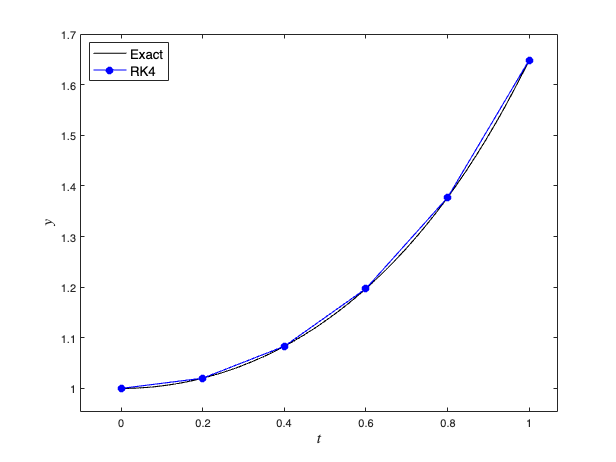

% Calculate exact solution for plotting
texact = linspace(tspan(1), tspan(2), 200);
yexact = exact(texact);

% Plot solution
plot(texact, yexact, 'k-', LineWidth=1)
hold on
plot(t, y, 'b-o', LineWidth=1, MarkerFaceColor='b')
hold off
axis padded
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y$', FontSize=14, Interpreter='latex')
legend('Exact', 'RK4', Location='northwest', FontSize=12)

#### Comparing errors for different methods

% Calculate solution for decreasing step lengths
hvals = [0.2, 0.1, 0.05, 0.025];
E_euler = [];
E_rk2 = [];
E_rk4 = [];
for h = hvals
    [~, y_euler] = euler(f, tspan, y0, h);
    [~, y_rk2] = rk2(f, tspan, y0, h);
    [~, y_rk4] = rk4(f, tspan, y0, h);
    E_euler = [E_euler, abs(exact(t(end)) - y_euler(end))];
    E_rk2 = [E_rk2, abs(exact(t(end)) - y_rk2(end))];
    E_rk4 = [E_rk4, abs(exact(t(end)) - y_rk4(end))];
end

% Output table of errors (for loop is used to group print statements)
for i = 1 : 1
    fprintf('|   j   |   Euler  |   RK2    |   RK4    |')
    fprintf('|:-----:|:--------:|:--------:|:--------:|');
    for n = 1 : length(hvals)
        fprintf('\n| %1.3f | %1.2e | %1.2e | %1.2e |', hvals (n), E_euler(n), E_rk2(n), E_rk4(n))
    end
end

|   j   |   Euler  |   RK2    |   RK4    |

|:-----:|:--------:|:--------:|:--------:|


| 0.200 | 1.89e-01 | 5.45e-01 | 4.59e-06 |
| 0.100 | 1.02e-01 | 5.98e-01 | 2.64e-07 |
| 0.050 | 5.28e-02 | 6.23e-01 | 1.55e-08 |
| 0.025 | 2.69e-02 | 6.36e-01 | 9.33e-10 |

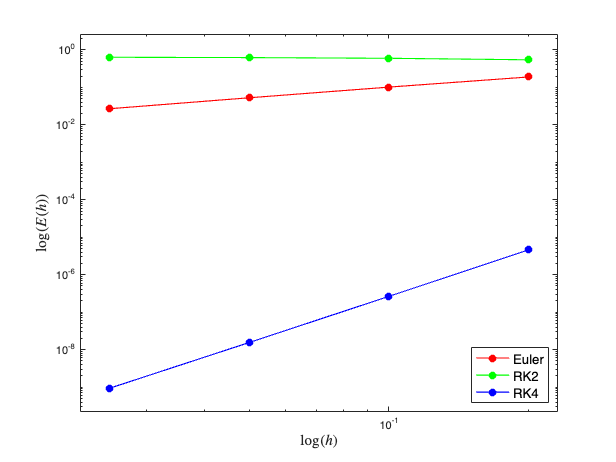


% Plot errors on a loglog scale
loglog(hvals, E_euler, 'ro-', MarkerFaceColor='r', LineWidth=1)
hold on
loglog(hvals, E_rk2, 'go-', MarkerFaceColor='g', LineWidth=1)
loglog(hvals, E_rk4, 'bo-', MarkerFaceColor='b', LineWidth=1)
hold off
axis padded
xlabel('$\log(h)$', FontSize=14, Interpreter='latex')
ylabel('$\log(E(h))$', FontSize=14, Interpreter='latex')
legend('Euler', 'RK2', 'RK4', Location='southeast', FontSize=12)

#### Example 2.8

The Bogacki-Shampine 2(3) embedded Runge-Kutta method has the Butcher tableau


$$    \begin{array}{c|cccc}
        0 & \\
        1/2 & 1/2 \\
        3/4 & 0 & 3/4 \\
        1 & 2/9 & 1/3 & 4/9 \\ \hline
        & 2/9 & 1/3 & 4/9 & 0 \\
        & 7/24 & 1/4 & 1/3 & 1/8
    \end{array}$$


where the first row of $b$ values gives a third-order method and the second row gives a second-order method. Use Bogacki-Shampine method to solve the following IVP using accuracy tolerances of $atol = 10^{-6}$ and $rtol = 10^{-3}$


$$y' = e^{t - y \sin(y)}, \qquad t \in [0, 5], \qquad y(0) = 0.$$


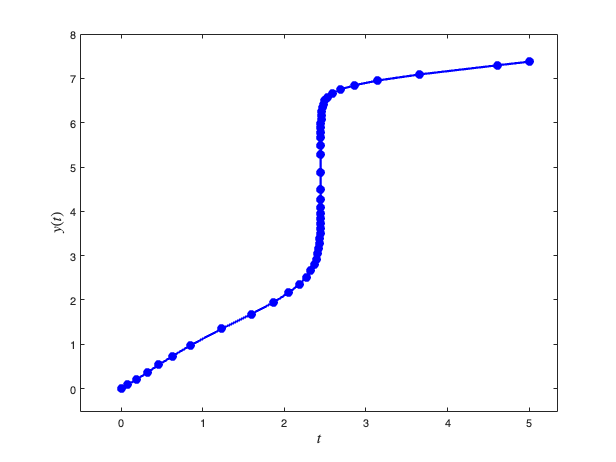

% Define ODE function
f = @(t, y) exp(t - y(1) * sin(y(1)));

% Define IVP parameters
tspan = [0, 5];     % boundaries of the t domain
y0 = 0;             % initial value of the solution
atol = 1e-6;        % absolute tolerance
rtol = 1e-3;        % relative tolerance

% Calculate the solution to the IVP
[t, y] = rk23(f, tspan, y0, atol, rtol);

% Plot solution
plot(t, y, 'b-o', LineWidth=2, MarkerFaceColor='b')
axis padded
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y(t)$', FontSize=14, Interpreter='latex')

#### Example 2.9

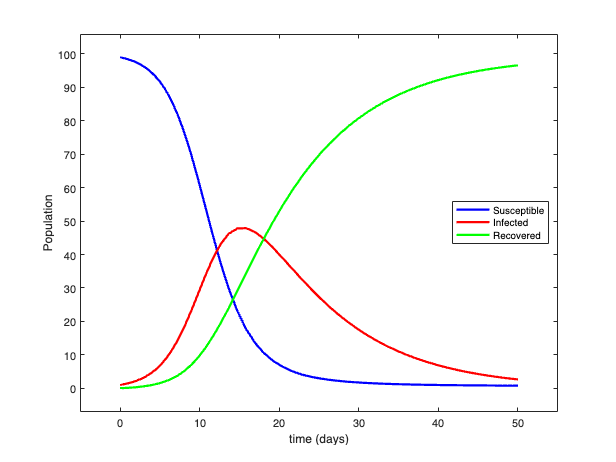

% Define IVP parameters
tspan = [0, 50];    % boundaries of the t domain
y0 = [99, 1, 0];    % initial value of the solution
beta = 0.5;         % infection rate
gamma = 0.1;        % recovery rate

% Solve IVP
[t, y] = ode45(@(t, y)SIR(t, y, beta, gamma), tspan, y0);

% Plot solution
plot(t, y(:,1), 'b', LineWidth=2)
hold on
plot(t, y(:,2), 'r', LineWidth=2)
plot(t, y(:,3), 'g', LineWidth=2)
hold off
xlabel('time (days)')
ylabel('Population')
legend('Susceptible', 'Infected', 'Recovered', Location="east")
axis padded

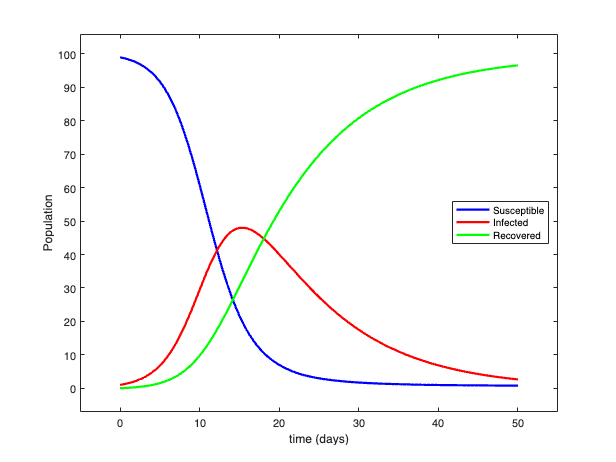

% Solve IVP
tspan = linspace(0, 50, 101);
[t, y] = ode45(@(t, y)SIR(t, y, beta, gamma), tspan, y0);

% Plot solution
plot(t, y(:,1), 'b', LineWidth=2)
hold on
plot(t, y(:,2), 'r', LineWidth=2)
plot(t, y(:,3), 'g', LineWidth=2)
hold off
xlabel('time (days)')
ylabel('Population')
legend('Susceptible', 'Infected', 'Recovered', Location="east")
axis padded

opt = odeset(Stats="on");
[t, y] = ode45(@(t, y)SIR(t, y, beta, gamma), tspan, y0, opt);

17 successful steps
0 failed attempts
103 function evaluations


## Functions

#### RK4 Method

function [t, y] = rk4(f, tspan, y0, h)

nsteps = floor((tspan(2) - tspan(1)) / h);
N = length(y0);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, N);
t(1) = tspan(1);
y(1,:) = y0;

for n = 1 : length(t) - 1
    k1 = f(t(n), y(n,:));
    k2 = f(t(n) + 1/2 * h, y(n,:) + 1/2 * h * k1);
    k3 = f(t(n) + 1/2 * h, y(n,:) + 1/2 * h * k2);
    k4 = f(t(n) + h, y(n,:) + h * k3);
    y(n+1,:) = y(n,:) + h / 6 * (k1 + 2 * k2 + 2 * k3 + k4);
    t(n+1) = t(n) + h;
end

end

#### Euler method

function [t, y] = euler(f, tspan, y0, h)

nsteps = floor((tspan(2) - tspan(1)) / h);
m = length(y0);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, m);
t(1) = tspan(1);
y(1,:) = y0;

for n = 1 : length(t) - 1
    y(n+1,:) = y(n,:) + h * f(t(n), y(n,:));
    t(n+1) = t(n) + h;
end

y = y';

end

#### RK2 method

function [t, y] = rk2(f, tspan, y0, h)

nsteps = floor((tspan(2) - tspan(1)) / h);
m = length(y0);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, m);
t(1) = tspan(1);
y(1,:) = y0;

for n = 1 : length(t) - 1
    k1 = f(t(n), y(n,:));
    k2 = f(t(n) + h, y(n,:) + h * k1);
    y(n+1,:) = y(n,:) + h / 2 * (k1 + k2);
    t(:, n+1) = t(n) + h;
end

y = y';

end

#### Fehlberg 5(4) Method

function [t, y] = rkf45(f, tspan, y0, atol, rtol)

m = length(y0);
t = zeros(100000, 1);
y = zeros(100000, m);
t(1) = tspan(1);
y(1,:) = y0;

h = 0.8 * rtol ^ (1/5);
n = 1;
while t(n) < tspan(2)

    k1 = f(t(n), y(n,:));
    k2 = f(t(n) + 1/4 * h, y(n,:) + 1/4 * h * k1);
    k3 = f(t(n) + 3/8 * h, y(n,:) + h * (3/32 * k1 + 9/32 * k2));
    k4 = f(t(n) + 12/13 * h, y(n,:) + h * (1932/2197 * k1 - 7200/2197 * k2 + 7296/2197 * k3));
    k5 = f(t(n) + h, y(n,:) + h * (439/216 * k1 - 8 * k2 + 3680/513 * k3 - 845/4104 * k4));
    k6 = f(t(n) + 1/2 * h, y(n,:) + h * (-8/27 * k1 + 2 * k2 - 3544/2565 * k3 + 1859/4104 * k4 - 11/40 * k5));
    
    y5 = y(n,:) + h * (16/135 * k1 + 6656/12825 * k3 + 28561/56430 * k4 - 9/50 * k5 + 2/55 * k6);
    y4 = y(n,:) + h * (25/216 * k1 + 1408/2565 * k3 + 2197/4104 * k4 - 1/5 * k5);

    delta = norm(y5 - y4);
    tol = atol + rtol * min(abs(y5));
    if delta < tol
        y(n+1,:) = y5;
        t(n+1) = t(n) + h;
        n = n + 1;
    end

    r = max(0.1, 0.8 * (tol / delta) ^ (1/5));
    h = min(r * h, tspan(2) - t(n));
end

t(n+1:end) = [];
y(n+1:end,:) = [];

end

#### Bogacki-Shampine 3(2) embedded Runge-Kutta method

function [t, y] = rk23(f, tspan, y0, atol, rtol)

m = length(y0);
t = zeros(100000, 1);
y = zeros(100000, m);
t(1) = tspan(1);
y(1,:) = y0;

h = 0.8 * rtol ^ (1/3);
n = 1;
while t(n) < tspan(2)

    k1 = f(t(n), y(n,:));
    k2 = f(t(n) + 1/2 * h, y(n,:) + 1/2 * h * k1);
    k3 = f(t(n) + 3/4 * h, y(n,:) + 3/4 * h * k2); 
    k4 = f(t(n) + h, y(n,:) + h * (2/9 * k1 + 1/3 * k2 + 4/9 * k3));
    y3 = y(n,:) + h * (2/9 * k1 + 1/3 * k2 + 4/9 * k3); 
    y2 = y(n,:) + h * (7/24 * k1 + 1/4 * k2 + 1/3 * k3 + 1/8 * k4);

    delta = norm(y3 - y2);
    tol = atol + rtol * min(abs(y3));
    if delta < tol
        y(n+1,:) = y3;
        t(n+1) = t(n) + h;
        k1 = k4;
        n = n + 1;
    end

    r = max(0.1, 0.8 * (tol / delta) ^ (1/3));
    h = min(r * h, tspan(2) - t(n));
end

t(n+1:end) = [];
y(n+1:end,:) = [];

end

#### SIR Model

function y = SIR(~, y, beta, gamma)

S = y(1); 
I = y(2);
R = y(3);
N = S + I + R;
y = [ -beta / N * I * S ;
       beta / N * I * S - gamma * I;
       gamma * I ];

end